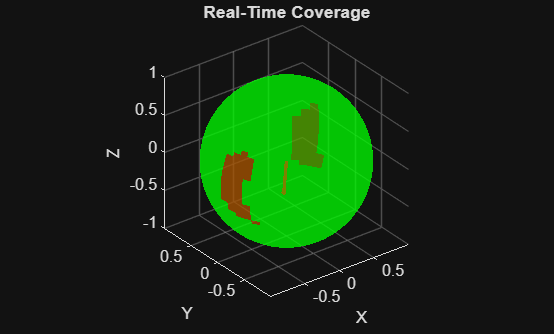

figure;

% --- Sphere grid ---
n = 60;
[phi, theta] = meshgrid(linspace(0,2*pi,n), linspace(0,pi,n));

X = sin(theta).*cos(phi);
Y = sin(theta).*sin(phi);
Z = cos(theta);

sphere_pts = [X(:), Y(:), Z(:)]';
Npts = size(sphere_pts,2);

covered = false(1, Npts);

% --- FOV ---
fov_half = deg2rad(30);

% --- Figure setup ---
figure;
hSurf = surf(X, Y, Z, zeros(size(X)), 'EdgeColor', 'none','FaceAlpha',0.5);
axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Real-Time Coverage');
colormap([1 0 0; 0 1 0]); % blue -> yellow
clim([0 1]);

% camlight;
% lighting phong;
hold on;

% Camera boresight vector plot
hVec = quiver3(0,0,0,0,0,1,'r','LineWidth',2);

% --- Loop through time ---
for k = 1:length(t)
    
    % Rotation matrix
    R = quat2rotm(q(k,:));
    
    % Boresight
    v = R * [1;0;0];
    
    % Dot products
    dots = v' * sphere_pts;
    
    % Update coverage
    covered = covered | (dots >= cos(fov_half));
    
    % Reshape for plotting
    covered_map = reshape(covered, size(X));
    
    % Update surface colors
    set(hSurf, 'CData', double(covered_map));
    
    % Update boresight vector
    set(hVec, 'UData', v(1), 'VData', v(2), 'WData', v(3));
    
    drawnow;
end